# Mesh Generation

## Figure geometry and write data

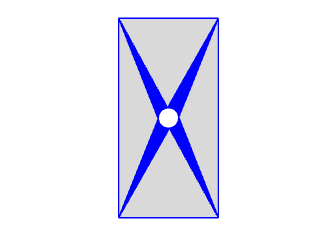

clear;
TR = stlread("PlateHolePlanar.stl");

nodes = (TR.Points(:,1:2))';
elements = (TR.ConnectivityList)';
edges = freeBoundary(TR)';

geometrywrite(nodes, elements, edges, 'geometry.dat');

%[nodes, elements, edges] = geometryread('geometry.dat');
figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','blue');
% hold on
% text(nodes(1,:),nodes(2,:), 'n' + string(1:size(nodes,2)));

% hold on
% plot([nodes(1, edges(1,:));nodes(1, edges(2,:))] , ...
%      [nodes(2, edges(1,:)); nodes(2, edges(2,:))], ...
%      Color = 'r', Marker='.',MarkerEdgeColor='b', MarkerSize = 8);

% hold on
% text((nodes(1, edges(1,:)) + nodes(1, edges(2,:)))/2, ...
%      (nodes(2, edges(1,:)) + nodes(2, edges(2,:)))/2, ...
%     'e' + string(1:size(edgees,2)));

axis equal off
exportgraphics(gca,'PlateHolePlanar-Geo.pdf','ContentType','vector');

## Example 1: Default

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat'); %
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

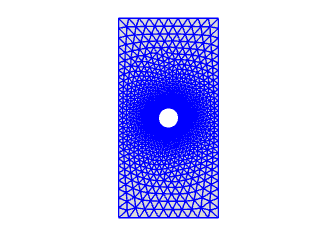

figure; 
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'PlateHolePlanar-Mesh.pdf','ContentType','vector');

### Figure Mesh with Bubbles

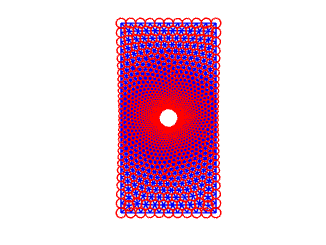

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

%exportgraphics(gca,'PlateHolePlanar-MeshRadii.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

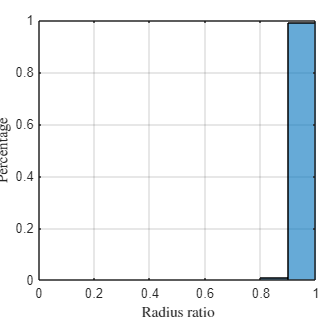

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 2: Hgrad

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hgrad=2); 
[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

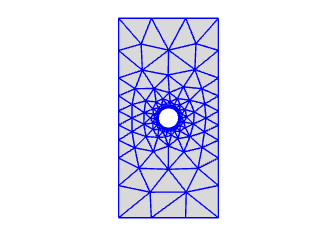

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'PlateHolePlanar-MeshHgrad.pdf','ContentType','vector');

### Figure Mesh with Bubbles

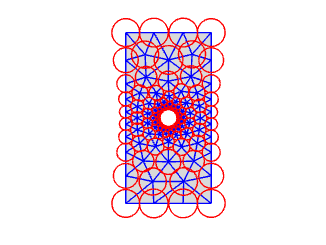

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

%exportgraphics(gca,'PlateHolePlanar-MeshRadii.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

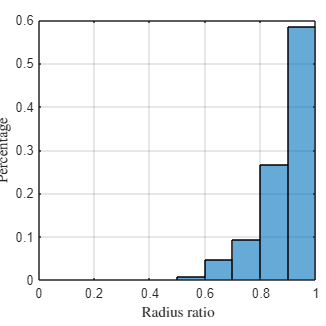

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on

## Example 3: Hmax

### Mesh generation and Read mesh file ('meshradii.dat')

meshgeneration('geometry.dat','meshradii.dat', Hmax=0.7); 

Iteration in progress, number of current nodes: 1293 
Iteration in progress, number of current nodes: 1366 


[nodes, elements, radii] = meshradiiread('meshradii.dat');

### Figure Mesh

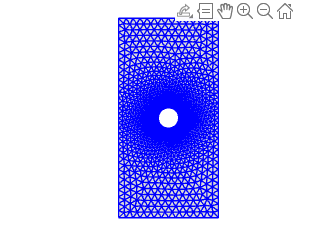

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

axis equal off
exportgraphics(gca,'PlateHolePlanar-MeshHmax.pdf','ContentType','vector');

### Figure Mesh with Bubbles

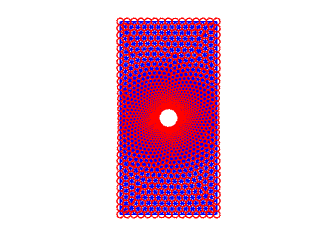

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on  
for i=1:length(radii)
    r=radii(i);
    if r < 1e10
        rectangle('Position',[nodes(1,i)-r, nodes(2,i)-r, 2*r, 2*r], ...
    'Curvature', [1 1], 'EdgeColor','r');
    end
end
axis equal off

%exportgraphics(gca,'PlateHolePlanar-MeshRadii.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

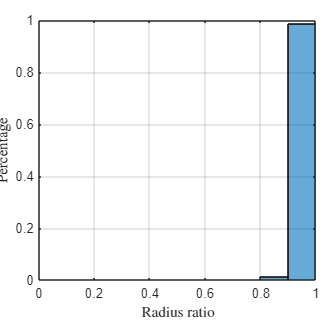

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on